clear;

data =  readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Project\wine_quality_df_cleaned.csv');

data;

X = data(:, [1:13]);
Y = data(:, 14);

[numSamples, ~] = size(X)

numSamples = 2477

splitRatio = 0.7;

numTrainSamples = floor(numSamples * splitRatio);

indices = randperm(numSamples);

x_train = X(indices(1:numTrainSamples), :);
y_train = Y(indices(1:numTrainSamples), :);
x_test = X(indices(numTrainSamples+1:end), :);
y_test = Y(indices(numTrainSamples+1:end), :);

X_train = table2array(x_train);
Y_train = table2array(y_train);
X_test = table2array(x_test);
Y_test = table2array(y_test);

% Create Random Forest
numTrees = 100;
randomForestModel = TreeBagger(numTrees, X_train, Y_train, 'Method', 'classification');

% Make predictions
[predictedLabels, scores] = predict(randomForestModel, X_test);

% Assuming Y_test is a numeric arracy or a different format
Y_test_str = string(Y_test);
predictedLabels_str = string(predictedLabels);

% Evaluate the model
accuracy = sum(predictedLabels_str == Y_test_str) / numel(Y_test_str);
% Display accuracy
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 86.5591%


% Evaluate the model
confMat = confusionmat(Y_test_str, predictedLabels_str);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

   116     0     2     1     0     0
     0    98     0     0     1     0
     0     0   107    11     1     0
     0     0     6    95    40     1
     0     0     0    32   101     0
     0     0     0     2     3   127



numClasses = size(confMat, 1);
precision = zeros(1, numClasses);
recall = zeros(1, numClasses);
f1_score = zeros(1, numClasses);

for i = 1:numClasses
    TP = confMat(i, i);
    FP = sum(confMat(:, i)) - TP;
    FN = sum(confMat(i, :)) - TP;
    
    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);
    f1_score(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
end

avgPrecision = mean(precision);
avgRecall = mean(recall);
avgF1Score = mean(f1_score);

% Display results
disp(['Average Precision: ', num2str(avgPrecision)]);

Average Precision: 0.88136


disp(['Average Recall: ', num2str(avgRecall)]);

Average Recall: 0.87573


disp(['Average F1 Score: ', num2str(avgF1Score)]);

Average F1 Score: 0.87817


% Calculate the observed agreement
po = sum(diag(confMat)) / sum(confMat(:));

% Calculate the chance agreement
pe = sum(sum(confMat, 1) .* sum(confMat, 2)) / sum(confMat(:))^2;

% Calculate Cohen's Kappa
kappa = (po - pe) / (1 - pe);

disp(['Cohen''s Kappa: ' num2str(kappa)]);

Cohen's Kappa: 0.83882


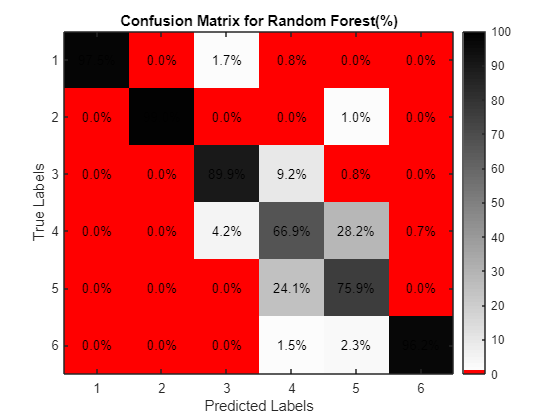

% Convert the confusion matrix to a percentage format
CM_percent = 100 * confMat ./ sum(confMat, 2);

% Define custom colormap with red background and white text
redBackground = [1, 0, 0];
blackText = [0, 0, 0];
whiteText = [1, 1, 1];

% Create a custom colormap with red background and shades of white for text
customColormap = [redBackground; interp1([0, 100], [whiteText; blackText], 1:100)];

% Visualize the confusion matrix as a heatmap using imagesc
figure;
h = imagesc(CM_percent);
colorbar;
colormap(customColormap);
clim([0, 100]); % Set the color axis range to match the percentages
title('Confusion Matrix for Random Forest(%)');
xlabel('Predicted Labels');
ylabel('True Labels');

% Display the percentage values on the heatmap in white or black based on intensity
textColors = repmat(CM_percent(:) > 50, 1, 3); % Define text colors based on background intensity
textStrings = strtrim(cellstr(num2str(CM_percent(:), '%.1f%%'))); % Convert values to string
[x, y] = meshgrid(1:size(CM_percent, 2), 1:size(CM_percent, 1)); % Create coordinate grid
text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center', 'Color', 'k');


% Display the diagonal values in white text on the heatmap

%for i = 1:size(CM_percent, 1)
%    text(i, i, num2str(CM_percent(i, i), '%.1f%%'), 'HorizontalAlignment', 'center', 'Color', 'w');
%    end87.6%

% Define the range of hyperparameters to search
minLeafSizes = [1, 5, 10, 20];
numPredictorsToSample = [1, 3, 5, 7];
maxNumSplits = [10, 20, 30, 40];

% Initializ variables to store the best results
bestAccuracy = 0;
bestHyperparameters = struct("MinLeafSize", 0, "NumPredictorsToSample", 0, "MaxNumSplits", 0);
bestModel = [];

% Initialize array to store accuracies
allAccuracies = zeros(length(minLeafSizes), length(numPredictorsToSample), length(maxNumSplits));

% Perform Grid Search
for i = 1:length(minLeafSizes)
    for j = 1:length(numPredictorsToSample)
        for k = 1:length(maxNumSplits)
            % Define hyperparameters
            minLeafSize = minLeafSizes(i);
            numPredictors = numPredictorsToSample(j);
            maxSplits = maxNumSplits(k);
            
            % Train the Random Forest model
            rfModel = TreeBagger(100, X_train, Y_train, 'Method', 'classification', ...
                                 'MinLeafSize', minLeafSize, ...
                                 'NumPredictorsToSample', numPredictors, ...
                                 'MaxNumSplits', maxSplits);
            
            % Make predictions and calculate accuracy
            [predictedLabels, ~] = predict(rfModel, X_test);
            predictedLabels = str2double(predictedLabels);
            accuracy = sum(predictedLabels == Y_test) / length(Y_test);
            
            % Display current hyperparameters and accuracy
            disp(['MinLeafSize: ' num2str(minLeafSize) ...
                  ', NumPredictorsToSample: ' num2str(numPredictors) ...
                  ', MaxNumSplits: ' num2str(maxSplits) ...
                  ', Accuracy: ' num2str(accuracy)]);
            
            % Update best model if accuracy is better
            if accuracy > bestAccuracy
                bestAccuracy = accuracy;
                bestHyperparameters.MinLeafSize = minLeafSize;
                bestHyperparameters.NumPredictorsToSample = numPredictors;
                bestHyperparameters.MaxNumSplits = maxSplits;
                bestModel = rfModel;
            end
            
            % Store accuracy in the array
            allAccuracies(i, j, k) = accuracy;
        end
    end
end

MinLeafSize: 1, NumPredictorsToSample: 1, MaxNumSplits: 10, Accuracy: 0.7836
MinLeafSize: 1, NumPredictorsToSample: 1, MaxNumSplits: 20, Accuracy: 0.80645
MinLeafSize: 1, NumPredictorsToSample: 1, MaxNumSplits: 30, Accuracy: 0.84005
MinLeafSize: 1, NumPredictorsToSample: 1, MaxNumSplits: 40, Accuracy: 0.84005
MinLeafSize: 1, NumPredictorsToSample: 3, MaxNumSplits: 10, Accuracy: 0.8078
MinLeafSize: 1, NumPredictorsToSample: 3, MaxNumSplits: 20, Accuracy: 0.83602
MinLeafSize: 1, NumPredictorsToSample: 3, MaxNumSplits: 30, Accuracy: 0.83871
MinLeafSize: 1, NumPredictorsToSample: 3, MaxNumSplits: 40, Accuracy: 0.84946
MinLeafSize: 1, NumPredictorsToSample: 5, MaxNumSplits: 10, Accuracy: 0.83333
MinLeafSize: 1, NumPredictorsToSample: 5, MaxNumSplits: 20, Accuracy: 0.8414
MinLeafSize: 1, NumPredictorsToSample: 5, MaxNumSplits: 30, Accuracy: 0.84677
MinLeafSize: 1, NumPredictorsToSample: 5, MaxNumSplits: 40, Accuracy: 0.85349
MinLeafSize: 1, NumPredictorsToSample: 7, MaxNumSplits: 10, Accurac

% Display all accuracies
disp('All Accuracies:');

All Accuracies:


disp(allAccuracies);


(:,:,1) =

    0.7836    0.8078    0.8333    0.8333
    0.7944    0.8105    0.8212    0.8347
    0.7688    0.8091    0.8226    0.8226
    0.7796    0.8051    0.8226    0.8266


(:,:,2) =

    0.8065    0.8360    0.8414    0.8387
    0.8266    0.8347    0.8374    0.8427
    0.8132    0.8320    0.8280    0.8454
    0.8011    0.8401    0.8401    0.8374


(:,:,3) =

    0.8401    0.8387    0.8468    0.8481
    0.8333    0.8374    0.8414    0.8468
    0.8333    0.8401    0.8468    0.8454
    0.8360    0.8454    0.8427    0.8401


(:,:,4) =

    0.8401    0.8495    0.8535    0.8548
    0.8347    0.8616    0.8535    0.8508
    0.8360    0.8522    0.8441    0.8454
    0.8374    0.8508    0.8441    0.8333




% Display best hyperparameters and accuracy
disp(['Best MinLeafSize: ' num2str(bestHyperparameters.MinLeafSize)]);

Best MinLeafSize: 5


disp(['Best NumPredictorsToSample: ' num2str(bestHyperparameters.NumPredictorsToSample)]);

Best NumPredictorsToSample: 3


disp(['Best MaxNumSplits: ' num2str(bestHyperparameters.MaxNumSplits)]);

Best MaxNumSplits: 40


disp(['Best Accuracy: ' num2str(bestAccuracy)]);

Best Accuracy: 0.86156


% Define hyperparameters
numTrees = 100; % Number of trees in the forest
minLeafSize = 5;
numPredictorsToSample = 3;
maxNumSplits = 40;

% Create the Random Forest model
final_rf_model = TreeBagger(numTrees, X_train, Y_train, ...
                            'Method', 'classification', ...
                            'MinLeafSize', minLeafSize, ...
                            'NumPredictorsToSample', numPredictorsToSample, ...
                            'MaxNumSplits', maxNumSplits);

[predictedLabels, scores] = predict(final_rf_model, X_test);

confMat2 = confusionmat(Y_test, str2double(predictedLabels));

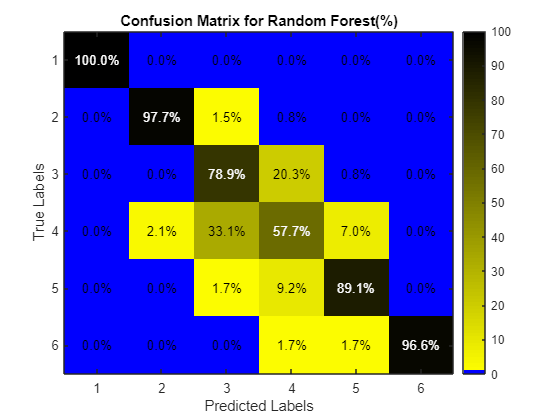

CM_percent = 100 * confMat2 ./ sum(confMat2, 2);

% Define custom colors
blueBackground = [0, 0, 1]; % Blue background
yellowText = [1, 1, 0]; % Yellow text
blackText = [0, 0, 0]; % Black text

% Create a custom colormap with blue background and shades of yellow for text
customColormap = [blueBackground; interp1([0, 100], [yellowText; blackText], 1:100)];

% Visualize the confusion matrix as a heatmap using imagesc
figure;
h = imagesc(CM_percent);
colorbar;
colormap(customColormap);
clim([0, 100]); % Set the color axis range to match the percentages
title('Confusion Matrix for Random Forest(%)');
xlabel('Predicted Labels');
ylabel('True Labels');

% Display the percentage values on the heatmap in white or black based on intensity
textColors = repmat(CM_percent(:) > 50, 1, 3); % Define text colors based on background intensity
textStrings = strtrim(cellstr(num2str(CM_percent(:), '%.1f%%'))); % Convert values to string
[x, y] = meshgrid(1:size(CM_percent, 2), 1:size(CM_percent, 1)); % Create coordinate grid
text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center', 'Color', 'k');

% Display the diagonal values in white text on the heatmap
for i = 1:size(CM_percent, 1)
    text(i, i, num2str(CM_percent(i, i), '%.1f%%'), 'HorizontalAlignment', 'center', 'Color', 'w');
end

% Feature Importance
%featureImportance = randomForestModel.OOBPermutedPredictorDeltaError;
%bar(featureImportance);